# Rotina para análise do BoteCon

## Definir inicio do movimento e da integração.

Este é o maior problema metodológico do projeto. Nos saltos verticais, um periodo entre 300 e 500ms com o participante imóvel sobre a plataforma é ultilizado para definir o peso e o valor de cinco desvios padrões para detectar automativamente o início do movimento. Outra dificuldade é estabelecer por meio desse procedimento o valor do peso  fazer a tara ( um valor arbitrario de peso causaria uma velocidade inicial diferente de zero.

No CB este procedimento é inviavel pois devido a tarefa, nota-se uma variação (tremor) no sinal da força.

Parametros Individuais para o processamento da curva força-tempo


Massa_Real = 81; % (kg) balança MUDAR para cada voluntario!!!!

Lastro = 0;        % (kg)MUDAR para cada tentativa!!!! resistência externa 

agarra = 1;        % MUDAR para cada tentativa!!!! 


Parametros gerais para o processamento da curva força-tempo

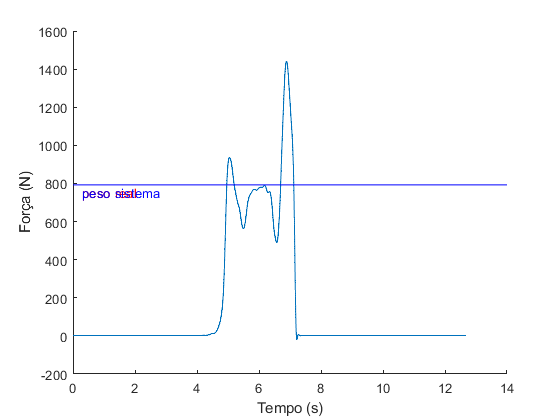

Fs=1000;% frequência de amostragem
g = 9.78; % aceleração da gravidade
Peso_real = Massa_Real*g;
Massa_lastro = Massa_Real + Lastro; % KG
Peso_lastro = Massa_lastro*g; % N
alcance_max = agarra*15;%(cm) distância de 15 cm entre as agarras.


figure
plot(t,Total);
hline(Peso_real, 'r', 'peso real')
hline(Peso_lastro, 'b','peso sistema' )
%vline(6.684, 'b', 'Trigger GoPro')% diferença entre o tempo GoproPDF e o tempo metadata (força)
box off
xlabel('Tempo (s)')
ylabel('Força (N)')

vA ideia é utlizar  o pico de força como critério para fazer um corte inicial e menos criterioso na curva com a finalidade de faciltar  o processamento de  dectar do inìcio do movimento.

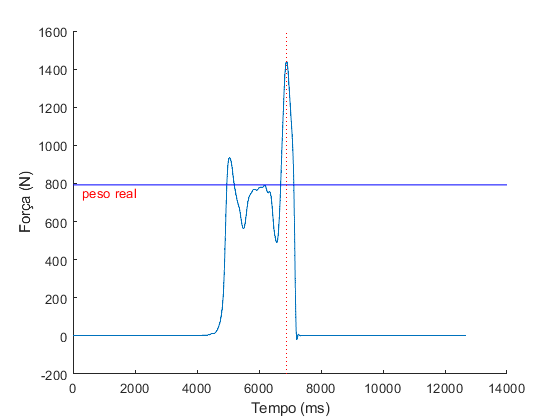

Pico = max(Total); % obtenho o valor pico de força
pico_Trigger = find(Total == Pico);% obtenho a posição (tempo) do valor de pico de força


figure
plot(Total);
hline(Peso_real, 'r', 'peso real')
hline(Peso_lastro, 'b')
vline(pico_Trigger)
box off
xlabel('Tempo (ms)')
ylabel('Força (N)')

Faz o corte inicial

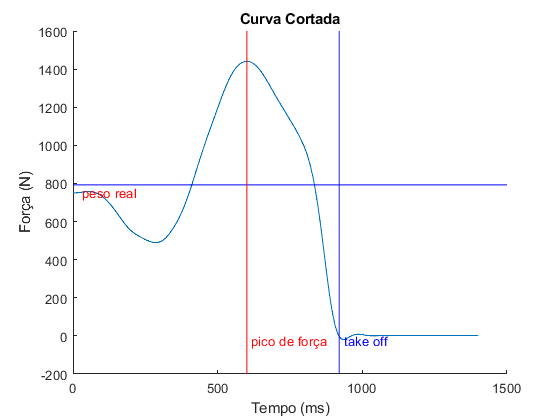

Total_corta = Total(pico_Trigger - 600:pico_Trigger + 800); 
% os valores de 1000 e 800 são arbitrarios e cortam a curva definindo quantos dados antes  e depois do pico serão incluidos.

fim_Trigger = find(Total_corta < 0, true,'first');% obtenho a posição ("tempo") quando a força passa por zero TAKE OFF.
pico_Trigger_cort = find(Total_corta == Pico);% obtenho a NOVA posição ("tempo") do valor de pico de força NA CURVA CORTADA

figure
plot(Total_corta);
title('Curva Cortada')
hline(Peso_real, 'r', 'peso real')
hline(Peso_lastro, 'b')
vline(pico_Trigger_cort, 'r', 'pico de força')
vline(fim_Trigger,'b', 'take off')
xlabel('Tempo (ms)')
ylabel('Força (N)')
box("off")

    Paramentros para detectar automaticamente o início do movimento e da integração. 

W_med = mean(Total_corta(1:300)); % peso considerando a média da força no inrtevalo determinado
W_max = max(Total_corta(1:300));% peso considerando o valor maximo de força no inrtevalo determinado
W_min = min(Total_corta(1:300));% peso considerando o valor mínimo de força no inrtevalo determinado

SD_otimo = 0.2;

SD5 = std(Total_corta(1:300))*SD_otimo;%!!!!!! desvio padrao dos valores de força no inrtevalo determinado



Detectar automaticamente o início do movimento e da integração.

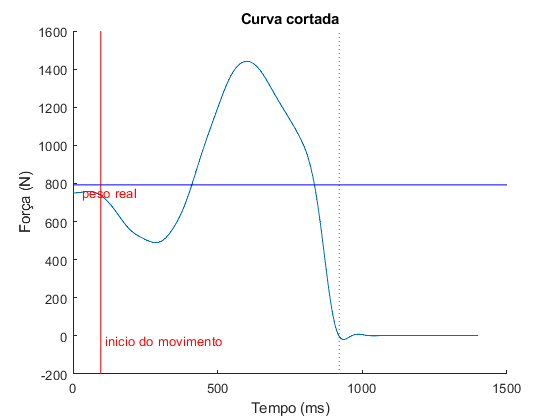

 if W_max >= W_med+SD5 % set condition if max weighing force is greater than or equal to bodweight + 5 SDs
        CMJ_Start11 = find(Total_corta > W_max+SD5,true); % Search for pre-loading initiation of jump
        CMJ_Start12 = find(Total_corta(:,1) < W_max-SD5,true); % Search for unloading initiation of jump
  elseif W_max < W_med+SD5 % set secondary condition if max weighing force is less than  bodweight + 5 SDs
        CMJ_Start11 = find(Total_corta > W_med+SD5,true); % Search for pre-loading initiation of jump
        CMJ_Start12 = find(Total_corta < W_med-SD5,true); % Search for pre-loading initiation of jump 
  end 
  
  if CMJ_Start11 < CMJ_Start12 % set condition if whether pre-load occurs before unload 
        CMJ_Start = CMJ_Start11; % Start initiated using a pre-load
  else % if anything else occurs
        CMJ_Start = CMJ_Start12; % start initiated using an unload
  end
  
  figure
plot(Total_corta);
title('Curva cortada')
xlabel('Tempo (ms)')
ylabel('Força (N)')
box("off")
vline(CMJ_Start, 'r', "inicio do movimento" )
vline(fim_Trigger)
hline(Peso_real, 'r', 'peso real')
hline(Peso_lastro, 'b')

#### Essa parte da rotina faz a tara do sinal. Para isso será considerado o valor de força  no ponto referente ao inicio do movimento. Confirmar em reunião do biolab

tara = Total_corta(CMJ_Start) %deteca o valor para tarar

tara = 736.7189

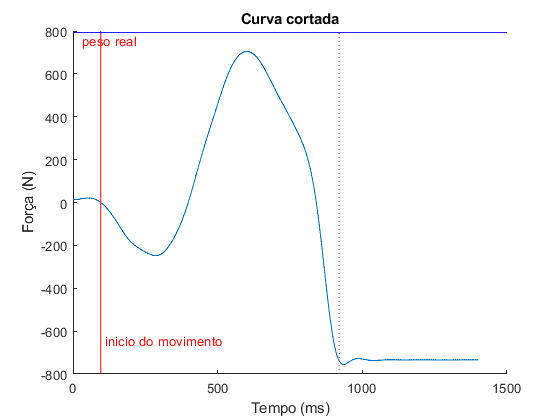

massa_tara = tara/g;
  
Total_tara = Total_corta-tara;

figure
plot(Total_tara);
title('Curva cortada')
xlabel('Tempo (ms)')
ylabel('Força (N)')
box("off")
vline(CMJ_Start, 'r', "inicio do movimento" )
vline(fim_Trigger)
hline(Peso_real, 'r', 'peso real')
hline(Peso_lastro, 'b')

# Com a curva de força zerada temos que cortar o que será integrado.

primeira opção e cortar no inicio do movimento e take off.

o valor da massa será o valor da tara dividido por "g"

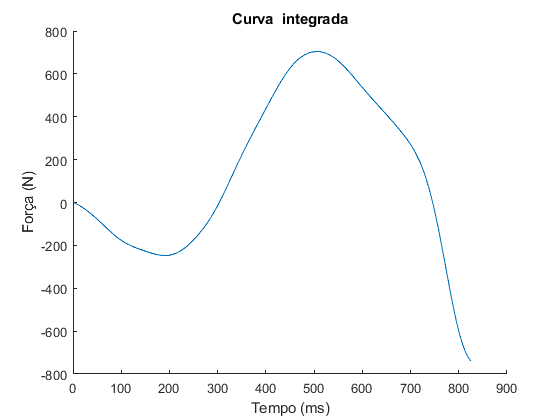

Total_Tratado_1 = Total_tara(CMJ_Start:fim_Trigger);% duvida no finaç da integração. vai no zero ou passa um pouco.

figure;
plot(Total_Tratado_1);
title('Curva  integrada')
xlabel('Tempo (ms)')
ylabel('Força (N)')
box("off")

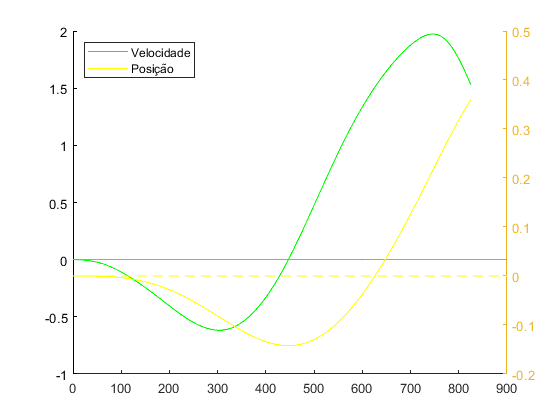


time_1 = ((1/Fs)*(0:length(Total_Tratado_1)-1))'; % ao salvar este tempo eu posso estar impedindo a analises para baixo 
accel_1 = Total_Tratado_1/massa_tara; %%% IMPORTANTE  Aqui é  x da quasão. qual o valor de W e de Massa? no caso 1 valor de tara/ g
Velo_curva_1 = cumtrapz(time_1, accel_1);
Posicao_curva_1 = cumtrapz(time_1,Velo_curva_1);


figure;
title('Velocidade e deslocamento')
xlabel('tempo (ms)')
ylabel('Força (N)')
box("off")
plot(Velo_curva_1,'g');
box("off")
hline (0,'g');
yyaxis right;
plot(Posicao_curva_1, 'y');
box("off")
hline (0,'y');
legend('Velocidade','Posição','Location','northwest')

   segunda opção opção e cortar no inicio do movimento e take off

o valor da massa será o real

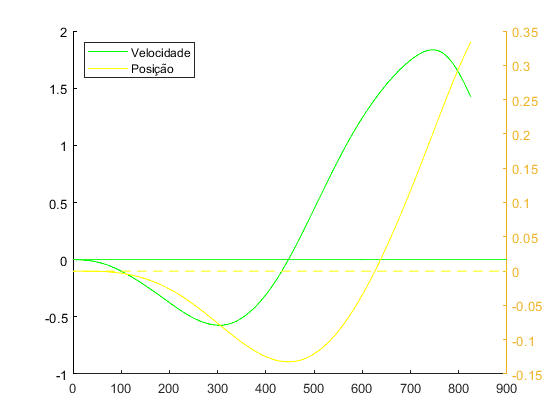

time_2 = ((1/Fs)*(0:length(Total_Tratado_1)-1))'; % ao salvar este tempo eu posso estar impedindo a analises para baixo 
accel_2 = Total_Tratado_1/Massa_Real; %%% IMPORTANTE  Aqui é  x da quasão. qual o valor de W e de Massa? no caso 1 valor de tara/ g
Velo_curva_2 = cumtrapz(time_2, accel_2);
Posicao_curva_2 = cumtrapz(time_2,Velo_curva_2);
figure;
title('Velocidade e deslocamento')
xlabel('tempo (ms)')
ylabel('Força (N)')
box("off")
plot(Velo_curva_2,'g');
box("off")
hline (0,'g');
yyaxis right;
plot(Posicao_curva_2, 'y');
box("off")
hline (0,'y');
legend('Velocidade','Posição','Location','northwest')

terceira opção opção e cortar no inicio do movimento até o fim da curva

o valor da massa será o valor da tara dividido por "g"

Total_Tratado_2 = Total_tara(CMJ_Start:end);% duvida no finaç da integração. vai no zero ou passa um pouco.

figure;
plot(Total_Tratado_1);
title('Curva  integrada')
xlabel('Tempo (ms)')
ylabel('Força (N)')
box("off")

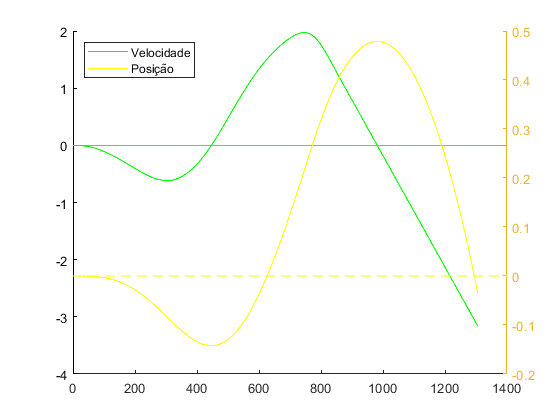

time_3 = ((1/Fs)*(0:length(Total_Tratado_2)-1))'; % ao salvar este tempo eu posso estar impedindo a analises para baixo 
accel_3 = Total_Tratado_2/massa_tara; %%% IMPORTANTE  Aqui é  x da quasão. qual o valor de W e de Massa? no caso 1 valor de tara/ g
Velo_curva_3 = cumtrapz(time_3, accel_3);
Posicao_curva_3 = cumtrapz(time_3,Velo_curva_3);
figure;
title('Velocidade e deslocamento')
xlabel('tempo (ms)')
ylabel('Força (N)')
box("off")
plot(Velo_curva_3,'g');
box("off")
hline (0,'g');
yyaxis right;
plot(Posicao_curva_3, 'y');
box("off")
hline (0,'y');
legend('Velocidade','Posição','Location','northwest')

quarta opção opção e cortar no inicio do movimento até o fim da curva

o valor da massa será o valor da massa real

accel_4 = Total_Tratado_2/Massa_Real; %%% IMPORTANTE  Aqui é  x da quasão. qual o valor de W e de Massa? no caso 1 valor de tara/ g
Velo_curva_4 = cumtrapz(time_3, accel_4);
Posicao_curva_4 = cumtrapz(time_3,Velo_curva_4);
figure;
title('Velocidade e deslocamento')
xlabel('tempo (ms)')
ylabel('Força (N)')
box("off")
plot(Velo_curva_3,'g');
box("off")
hline (0,'g');
yyaxis right;
plot(Posicao_curva_3, 'y');
box("off")
hline (0,'y');
legend('Velocidade','Posição','Location','northwest')

Calcular a curva de potência

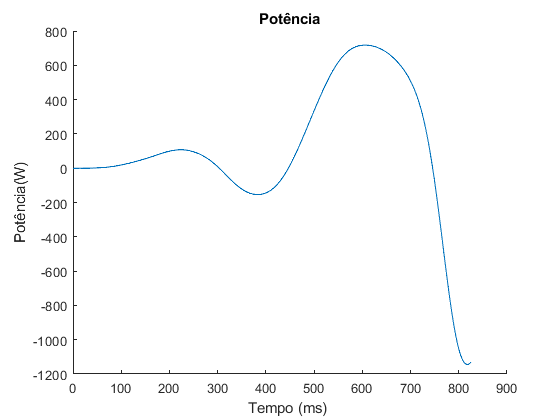

Potencia_curva_1 = (Total_Tratado_1.*Velo_curva_1);%%%% verificar se precisa de ponto logo apos a velocidade igual ao da força.
Potencia_curva_2 = (Total_Tratado_1.*Velo_curva_2);
Potencia_curva_3 = (Total_Tratado_2.*Velo_curva_3);
Potencia_curva_4 = (Total_Tratado_2.*Velo_curva_4);


figure;
plot(Potencia_curva_1);

title('Potência')
xlabel('Tempo (ms) ')
ylabel('Potência(W)')
box("off")

calcular  variaveis principais

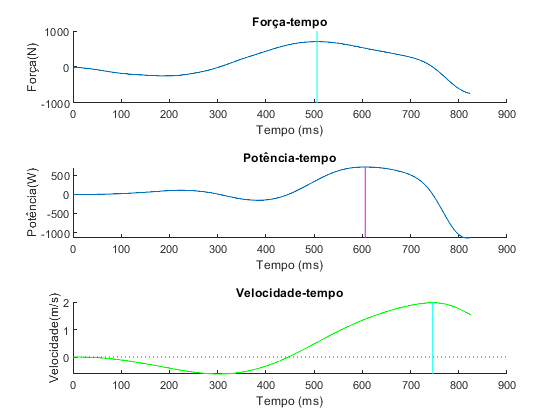

Pico_velo = max(Velo_curva_1);% (m/s)
Pico_velo2 = max(Velo_curva_2);
Pico_velo3 = max(Velo_curva_3);
Pico_velo4 = max(Velo_curva_4);
Velo_saida = Velo_curva_1(end);

Pico_de_forca = max(Total_Tratado_1);
Pico_forca_relativo = Pico_de_forca/Massa_Real;

Pico_Potencia = max(Potencia_curva_1);
Pico_pot_relativo = Pico_Potencia/Massa_Real;

Potencia_Calc = Pico_velo*Peso_lastro;
Potencia_Calc_2 = Pico_velo2*Peso_lastro;
Potencia_Calc_3 = Pico_velo3*Peso_lastro;
Potencia_Calc_4 = Pico_velo4*Peso_lastro;

Potencia_Calc_relativo = Pico_velo*Peso_lastro/Massa_Real;
Potencia_Calc_2_relativo = Pico_velo2*Peso_lastro/Massa_Real;
Potencia_Calc_3_relativo = Pico_velo3*Peso_lastro/Massa_Real;
Potencia_Calc_4_relativo = Pico_velo4*Peso_lastro/Massa_Real;



Impulso = trapz(Total_Tratado_1)/Fs; %??????


Loc_pico_forca = find(Total_Tratado_1 == Pico_de_forca);
Loc_pico_velo = find(Velo_curva_1 == Pico_velo);
Loc_pico_pot = find(Potencia_curva_1 == Pico_Potencia);
tiledlayout(3,1);

% Top plot
nexttile;
plot(Total_Tratado_1);
title('Força-tempo');
xlabel('Tempo (ms)')
ylabel('Força(N)')
box("off")
vline(Loc_pico_forca,'c');


%meio
nexttile;
plot(Potencia_curva_1);
title('Potência-tempo');
xlabel('Tempo (ms)')
ylabel('Potência(W)')
vline(Loc_pico_pot,'m');
box("off")

% Bottom plot
nexttile;
plot(Velo_curva_1, "g");
title('Velocidade-tempo');
hline(0);
ylabel('Velocidade(m/s)')
xlabel('Tempo (ms)')
vline(Loc_pico_velo,'c');
box("off")
hold on;

Análise da assimetria de força

Pico_de_forca_direita = max(dir_F);
Pico_de_forca_esquerda = max(esq_F);


Calcular as variaveis secundarias e temporais

Desloc_vert_CM = Velo_saida^2/19.62; %(m)
Momentum = Massa_lastro*Velo_saida; %(kg*s)
tempo_Bote = time_1(end)-time_1(1); %(ms)
tempo_ate_pico_forca = time_1(Loc_pico_forca)-time_1(1);
tempo_ate_pico_velo = time_1(Loc_pico_velo)-time_1(1);
tempo_ate_pico_pot = time_1(Loc_pico_pot)-time_1(1);
Potencia_media = Pico_Potencia/tempo_Bote;
Potencia_media_nor = Potencia_media/Massa_Real;


Faixas de tempo específicas 0–30, 0–50, 0–90, 0–100, 0–150, 0–200 e 0–250 0-300 (ms). 

Determina o valor de força inicial e os valores de força finais para calcular o delta força. 



Int_inic = 0;

Forca_Zero = Total_Tratado_1(1:1);% localiza o valor inicial do delta força.

Tempo_30 = Int_inic+30;
Forca_30 = Total_Tratado_1(Tempo_30);%localiza o valor final do delta força.

Tempo_50 = Int_inic+50;
Forca_50 = Total_Tratado_1(Tempo_50);%localiza o valor final do delta força.

Tempo_90 = Int_inic+90;
Forca_90 = Total_Tratado_1(Tempo_90);%localiza o valor final do delta força.

Tempo_100  = Int_inic+100; %localiza o 'frame'referente ao valor de força.
Forca_100 = Total_Tratado_1(Tempo_100);%localiza o valor final do delta força.

Tempo_150 = Int_inic+150;
Forca_150 = Total_Tratado_1(Tempo_150);%localiza o valor final do delta força.

Tempo_200 = Int_inic+200;
Forca_200 = Total_Tratado_1(Tempo_200);%localiza o valor final do delta força.

Tempo_250 = Int_inic+250;
Forca_250 = Total_Tratado_1(Tempo_250);%localiza o valor final do delta força.

Tempo_300 = Int_inic+300; % este é por minha conta devido a caracteristica da tarefa.
Forca_300 = Total_Tratado_1(Tempo_300);%localiza o valor final do delta força.

Tempo_400 = Int_inic+400; % este é por minha conta devido a caracteristica da tarefa.
Forca_400 = Total_Tratado_1(Tempo_400);%localiza o valor final do delta força.

Tempo_450 = Int_inic+450; % este é por minha conta devido a caracteristica da tarefa.
Forca_450 = Total_Tratado_1(Tempo_400);%localiza o valor final do delta força.



$$\textrm{Rate}\;\textrm{of}\;\textrm{Force}\;\textrm{Development}=\frac{\Delta \textrm{Força}}{\Delta \textrm{Tempo}}$$


TPF_med = (Pico_de_forca/tempo_ate_pico_forca); %unidade arbitraria The avgRFD, which is identical to the IES, was calculated from...
% the PF achieved and the elapsed time between the initiation of the pull (0) and the PF values
TPF_30 = (Forca_30-Forca_Zero)/(Tempo_30-Int_inic);
TPF_50 = (Forca_50-Forca_Zero)/(Tempo_50-Int_inic);
TPF_90 = (Forca_90-Forca_Zero)/(Tempo_90-Int_inic);
TPF_100 = (Forca_100-Forca_Zero)/(Tempo_100-Int_inic);
TPF_150 = (Forca_150-Forca_Zero)/(Tempo_150-Int_inic);
TPF_200 = (Forca_200-Forca_Zero)/(Tempo_200-Int_inic);
TPF_250 = (Forca_250-Forca_Zero)/(Tempo_250-Int_inic);
TPF_300 = (Forca_300-Forca_Zero)/(Tempo_300-Int_inic);
TPF_400 = (Forca_400-Forca_Zero)/(Tempo_400-Int_inic);
TPF_450 = (Forca_450-Forca_Zero)/(Tempo_450-Int_inic);

## Mudar nome

save('Curvas_V5Ex2T4A3_2kgd2.mat','Total_Tratado_1', 'Total_Tratado_2','accel_1','accel_2','accel_3','accel_4', 'Velo_curva_1', 'Velo_curva_2', 'Velo_curva_3', 'Velo_curva_4', 'Posicao_curva_1','Posicao_curva_2','Posicao_curva_3','Posicao_curva_4','Potencia_curva_1','Potencia_curva_2','Potencia_curva_3','Potencia_curva_4','time_1');

Exporta = [Pico_de_forca_direita Pico_de_forca_esquerda Massa_lastro agarra alcance_max Lastro Pico_pot_relativo Pico_Potencia Potencia_Calc Potencia_media Potencia_media_nor Pico_forca_relativo Pico_de_forca Pico_velo Desloc_vert_CM Impulso Momentum tara tempo_ate_pico_pot tempo_ate_pico_forca tempo_ate_pico_velo tempo_Bote W_max W_med W_min Forca_30 Forca_50 Forca_90 Forca_100 Forca_150 Forca_200 Forca_250 Forca_300 Forca_400 Forca_450 TPF_30 TPF_50 TPF_90 TPF_100 TPF_150 TPF_200 TPF_250 TPF_300 TPF_400 TPF_450 Pico_velo2 Pico_velo3 Pico_velo4];
T = array2table(Exporta,"VariableNames",{'Pico de força direita (N)' 'Pico de força esquerda (N)' 'Massa + lastro(kg)' 'Agarra' 'Alcançe(cm)' 'Lastro (kg)' 'Pico de potência normalizdado (W/kg)' 'Pico de potência (W)' 'Potência Calculado (W)' 'Potência média (W)' 'Potência média (W/kg)' 'Pico de Força relativo(N/kg)' 'Pico de Força (N)' 'Pico de velocidade (m/s)' 'Desloc vert cm (m)' 'Impulso (Ns)' 'Momento (KG x m/s)' 'tara(N)' 'tempo ate pico potência(ms)' 'tempo ate pico força(ms)' 'tempo ate pico velo(ms)' 'tempo Bote(ms)' 'Peso max (N)' 'Peso med (N)' 'Peso min (N)' 'Força em 30ms (N)' 'Força em 50ms (N)' 'Força em 90ms (N)' 'Força em 100ms (N)' 'Força em 150ms (N)' 'Força em 200ms (N)' 'Força em 250ms (N)' 'Força em 300ms (N)' 'Força em 400ms (N)' 'Força em 450ms (N)' 'TPF 30(N/s)' 'TPF 50(N/s)' 'TPF 90(N/s)' 'TPF 100(N/s)' 'TPF 150(N/s)' 'TPF 200(N/s)' 'TPF 250(N/s)' 'TPF 300(N/s)' 'TPF 400(N/s)' 'TPF 450(N/s)' 'Pico de velocidade2 (m/s)' 'Pico de velocidade3 (m/s)' 'Pico de velocidade 4 (m/s)'});
filename = 'dados_V5Ex2T4A3_2kgd2.xlsx';
writetable(T,filename,'Sheet',1,'Range','B1');

